# Classifying Urban Sounds8K Dataset using Machine Learning

Kevin Chng

## Overview :

            The credits for this example go to Ian Alfred. He drafted this example, I modified the example to explain my insight and solution.

            For this example, we are going to classify Urban sounds dataset using Machine Learning. Please be take note, i would not explain deep learning technique, although people generally believe deep learning technique could get higher accuracy. Let see what can we do with Machine Learning first.

            For this project we will use a dataset called Urbansound8K. The dataset contains 8732 sound excerpts (<=4s) of urban sounds from 10 classes, which are:

- Air Conditioner

- Car Horn

- Children Playing

- Dog bark

- Drilling

- Engine Idling

- Gun Shot

- Jackhammer

- Siren

- Street Music

The accompanying metadata contains a unique ID for each sound excerpt along with it's given class name. A sample of this dataset is included with the accompanying git repo and the full dataset can be downloaded from [here](https://urbansounddataset.weebly.com/urbansound8k.html).    

            There are 7 milestones in this example :

**Milestone 1** : Introduction to the Example, Explore and Visualize the Data

**Milestone 2 **: Data Pre-processing and Extracting Features using Diagnostic App Designer (Signal Time-Domain Features & Spectral Features)

**Milestone 3** : Model Training and Evaluation

**Milestone 4** : Model Deployment

**Milestone 5** : Extract Feature using MFCC to train Machine Learning Model

## **Highlights : **

- preparing the real life data for [audiodatastore](https://www.mathworks.com/help/audio/ref/audiodatastore.html)

- Standardize and normalize the digital signal data (Sample Rate, Bit-Depth, Number of Channel)

- Extract features with different approaches (Time-domain Signal features & Spectral Features, MFCC, *Discrete Wavelet Transform, Haar 1D Wavelet Transform*)

- Train machine learning model using classification learner app

- deploy machine learning model to embedded devices or desktop application

## **Product Focus :**

- MATLAB

- Audio Toobox

- Statistics and Machine Learning Toolbox

- Signal Processing Toolbox

- DSP System Toolbox

- Wavelet Toolbox

## **Flow :**

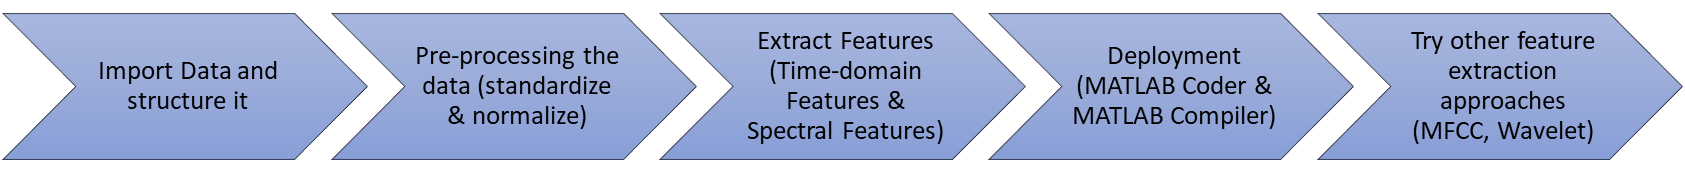

**Written at 19 November 2019**

## 1 Data Exploration and Visualisation

**Audio sample file data overview**

These sound excerpts are digital audio files in .wav format.

Sound waves are digitised by sampling them at discrete intervals known as the sampling rate (typically 44.1kHz for CD quality audio meaning samples are taken 44,100 times per second).

Each sample is the amplitude of the wave at a particular time interval, where the bit depth determines how detailed the sample will be also known as the dynamic range of the signal (typically 16bit which means a sample can range from 65,536 amplitude values).

This can be represented with the following image:

Therefore, the data we will be analysing for each sound excerpts is essentially a one dimensional array or vector of amplitude values.

## **Structure the data to categories in folder**

We will load a sample from each class and visually inspect the data for any patterns.

clear all
clc
warning("off")

%Import the dataset of each class
datafolder = "UrbanSound8K/audio";

%Labels Class/Categories
Data_Class = categorical(["Air Conditioner","Car Horn","Children Playing","Dog Bark","Drilling","Engine Idling","Gun Shot","Jackhammer","Siren","Street Music"]);

for i=1:1:length(Data_Class)
      mkdir(strcat("UrbanSound8K\structure1\",string(Data_Class(i))));
end
currentfolder = pwd;
cd(datafolder);
listdir=dir;
h=1;
L=1;
for i=4:1:length(listdir)
    cd(listdir(i).name)
    inside=dir;
    for k=4:1:length(inside)
    index=strfind(inside(k).name,'-');
    Labels(h)=Data_Class(str2num(inside(k).name(index(1)+1))+1);
    movefile(inside(k).name,strcat(currentfolder,"\UrbanSound8K\structure1\",string(Labels(h))));
    h=h+1;
    end
    cd(strcat(currentfolder,'\',datafolder));
end
cd(currentfolder)
clear all

## Visualize and Listen the Data (Wav. file)

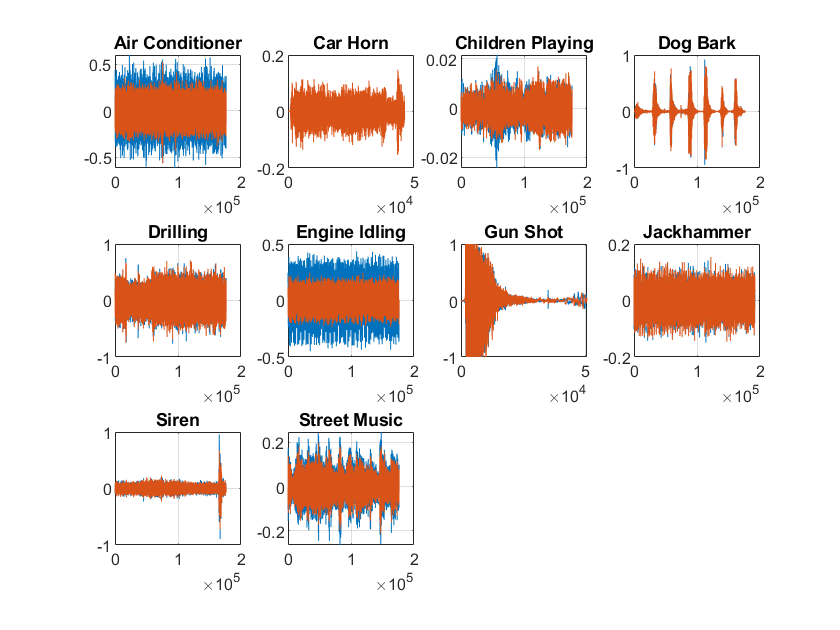

figure()
datafolder = "UrbanSound8K/structure1";
currentfolder = pwd;
cd(datafolder);
listdir=dir;  
for i=3:1:length(listdir)
    cd(listdir(i).name)
    inside=dir;
    subplot(3,4,i-2);
    [y,fs]=audioread(inside(4).name);
    plot(y(:,:)); 
    soundsc(y(:,:),fs);
    grid on;
    title(listdir(i).name)
    drawnow;
    pause(2)
    cd(strcat(currentfolder,'\',datafolder));
end
cd(currentfolder);
clear all

Observation :

1) The dataset is messy, therefore, i structure it into structured folders that audtiodatastore accepts it. You can see there are mono and stereo audio in the dataset.

2) However, as human, actually we can differenciate the sound using their shape of signal. Am I right? Now, we take note about it first.

3) From a visual inspection we can see that it is tricky to visualise the difference between some of the classes. Particularly, the waveforms for repetitive sounds for air conditioner, drilling, engine idling and jackhammer are similar in shape.

## Class Distributions

Let understand the distribution of dataset, here only use two commands : Damn cool !

1) audioDatastore

2) countEachLabel

datafolder = "UrbanSound8K/structure";

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')
G1=countEachLabel(ads)

Observation :

The dataset is imbalance, there are two classes (Car Horn and Gun Shot) have lesser amount compared to other 8 classes. How to handle the imbalance data is a popular topic in data science. Take note that Car Horn and Gun shot are lack of dataset at this moment, later we will fine tune the accurancy later by using some technique to deal with imbalance data : You may read the link below to have some concept how to deal with imbalance data.

[https://machinelearningmastery.com/tactics-to-combat-imbalanced-classes-in-your-machine-learning-dataset/](https://machinelearningmastery.com/tactics-to-combat-imbalanced-classes-in-your-machine-learning-dataset/)

## More insight : Digital Signal Processing 

Before going deeper to understand our dataset, i would like to put a stop here for coding, and let us understand the fundamental of Digital Signal :

Why do we need to understand the fundamental? It is because our dataset is messy, it comprised of different sample rate, bit depths or channels in the Wav. file, if we didn't normalize or standardize it, it might cause us not getting good accuracy model after training.

1) Sample Rate

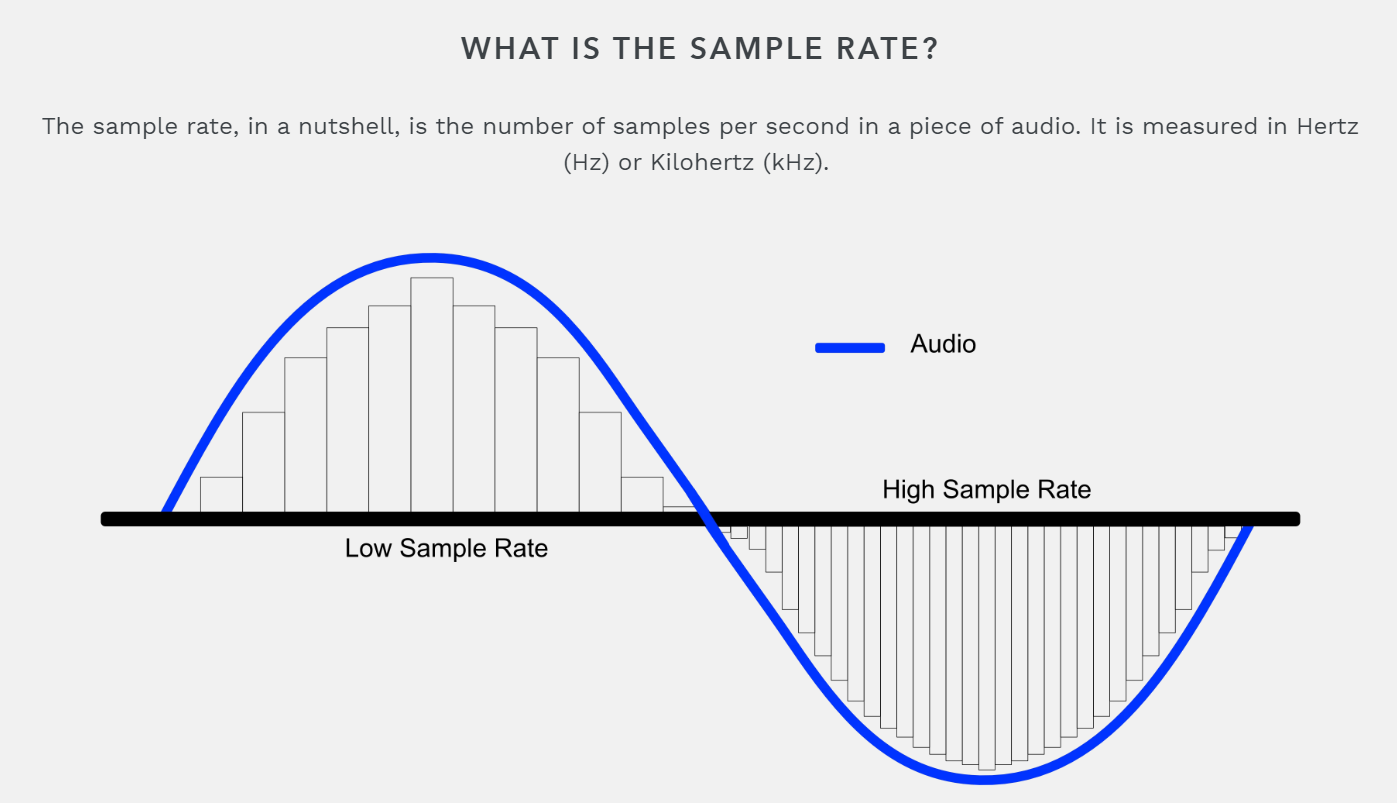

(Retrieved from : [https://www.masteringthemix.com/blogs/learn/113159685-sample-rates-and-bit-depth-in-a-nutshell](https://www.masteringthemix.com/blogs/learn/113159685-sample-rates-and-bit-depth-in-a-nutshell))

2) Bit Depth

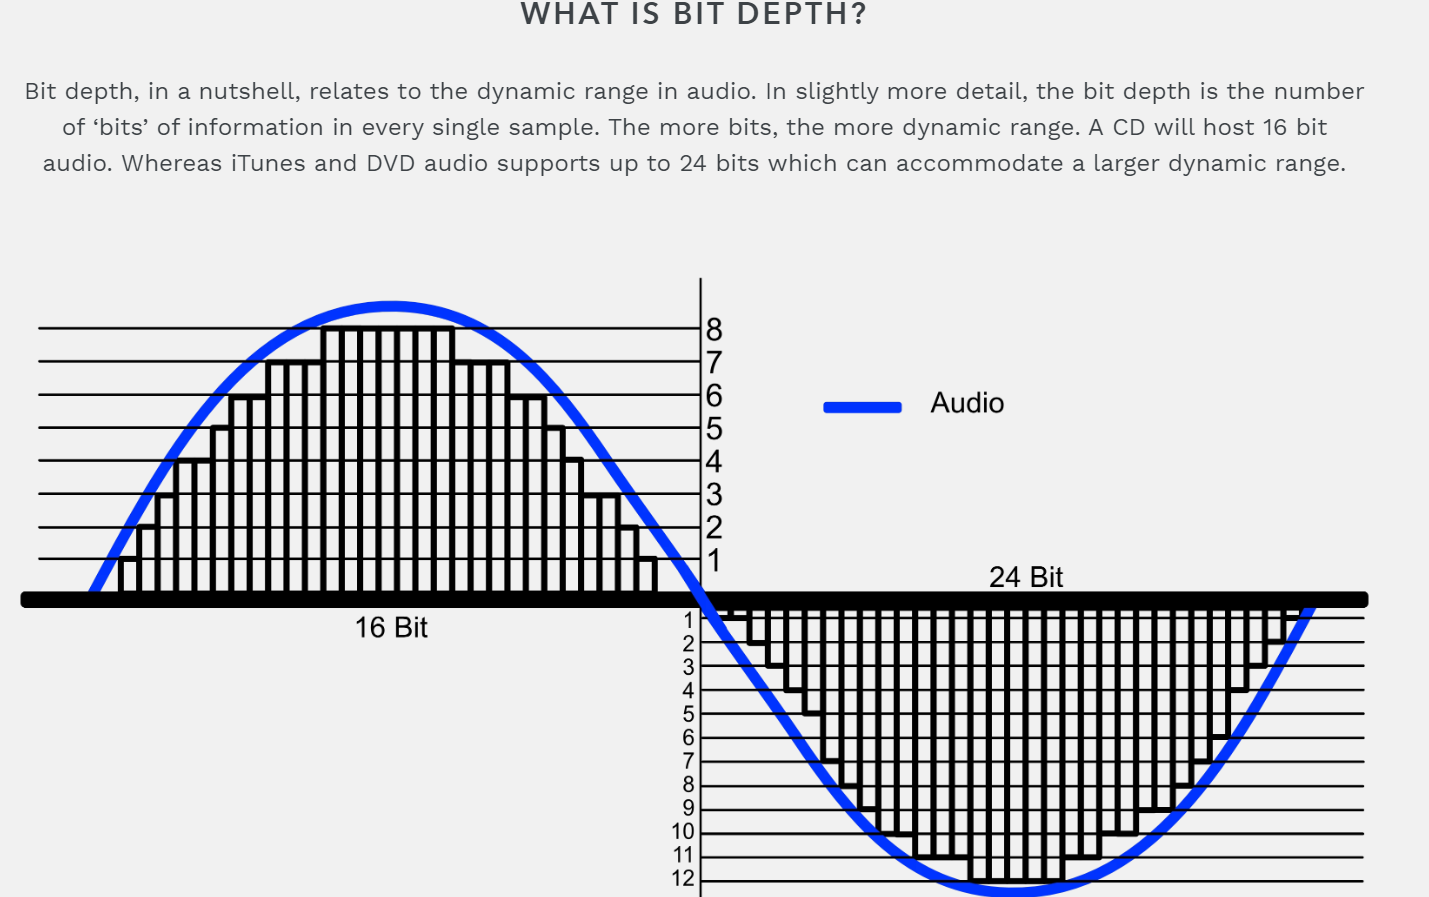

(Retrieved from : [https://www.masteringthemix.com/blogs/learn/113159685-sample-rates-and-bit-depth-in-a-nutshell](https://www.masteringthemix.com/blogs/learn/113159685-sample-rates-and-bit-depth-in-a-nutshell))

3) Channel

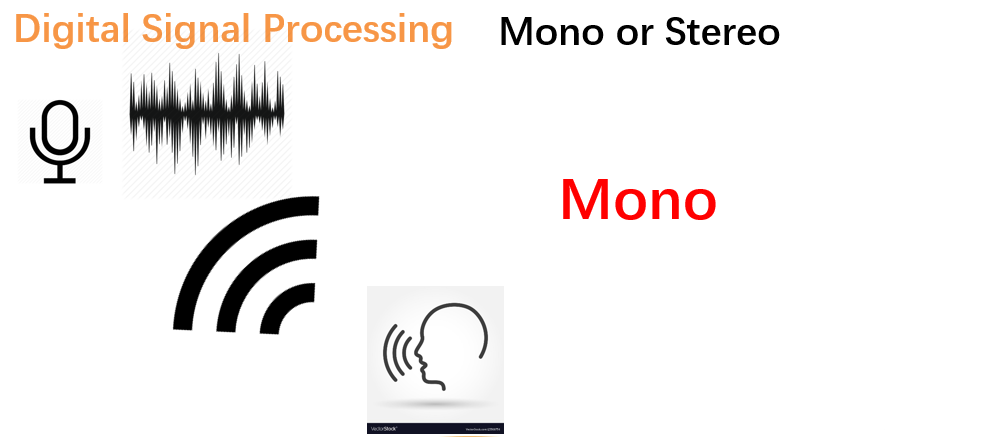    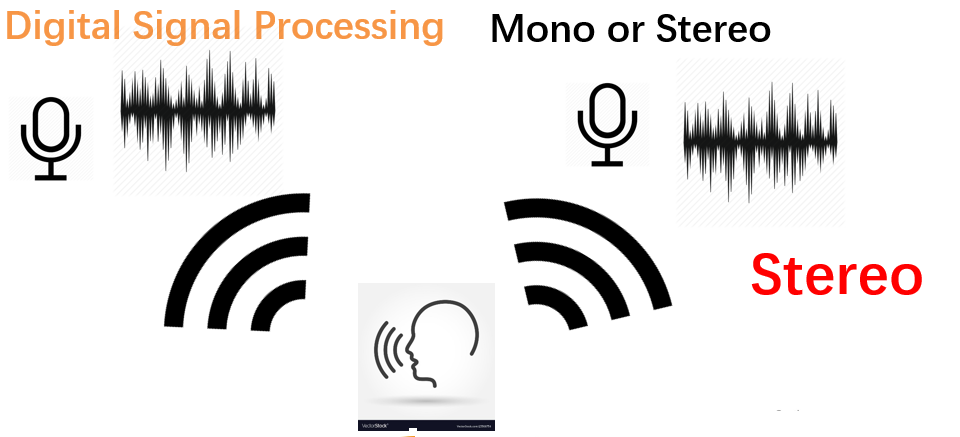

The number of channels tells us how many channels are there. We call it stereo when 2 channels are used, and call it mono when only one channel is used. Of course, mono sound can be played with more than one speaker, but it is still the exact same copy of the signal, which is played through the speakers. On the other hand, stereo is recorded with two different input channels of the same audio signal. What we normally see is stereo sound with left and right, this gives us a sense of directionality, perspective, space.

Now we have some of the important pieces of the puzzle to understand what the metadata of the dataset (WAVav file) is telling us.

## Audio Channels

Most of the samples have two audio channels (meaning stereo) with a few with just the one channel (mono).

The easiest option here to make them uniform will be to merge the two channels in the stero samples into one by averaging the values of the two channels.

%Check how much percentage of the data are Mono / Stereo
mono=1;
stereo=1;
for i=1:1:length(ads.Files)
    y=audioread(ads.Files{i});
    if size(y,2) == 1
        mono=mono+1;

ads =   audioDatastore with properties:

                       Files: {
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-0.wav';
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-1.wav';
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-10.wav'
                               ... and 8729 more
                              }
                      Labels: [Air Conditioner; Air Conditioner; Air Conditioner ... and 8729 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


    else

G1 = 10×2 table
         Label          Count
    ________________    _____

    Air Conditioner     1000 
    Car Horn             429 
    Children Playing    1000 
    Dog Bark            1000 
    Drilling            1000 
    Engine Idling       1000 
    Gun Shot             374 
    Jackhammer          1000 
    Siren                929 
    Street Music        1000 


        stereo=stereo+1;
    end
end

Percentage_Mono = mono/(mono+stereo)*100
Percentage_Stereo = stereo/(mono+stereo)*100

Observations: 8.47% dataset is mono and 91.53% is stereo. 

## **Sample rate**

There is a wide range of Sample rates that have been used across all the samples which is a concern (ranging from 96k to 8k).

This likley means that we will have to apply a sample-rate conversion technique (either up-conversion or down-conversion) so we can see an agnostic representation of their waveform which will allow us to do a fair comparison

%Check how much percentage of the data are on a specific Sampling Rate
for i=1:1:length(ads.Files)
    [y,fs(i)]=audioread(ads.Files{i});
end
Overall =table(categories(categorical(fs)),countcats(categorical(fs))');
Overall.Properties.VariableNames{1}='Frequency';
Overall.Properties.VariableNames{2}='Occurences'
%Plot the histogram distribution and explain
figure();
hist(categorical(fs))

Percentage_Mono = 8.4726

mode(fs)

Percentage_Stereo = 91.5274

Observations:

- 44100 frequency is the norm.

## **Bit-depth**

There is also a wide range of bit-depths. 

You may need to normalise them by taking the maximum and minimum amplitude values for a given bit-depth.

However, i'm going to resample all the Wav file to mode of bit depth in second milestone

%Check how much percentage of the data are recorded on a specific Bit depth
for i=1:1:length(ads.Files)
    info = audioinfo(ads.Files{i});
    if strcmp(info.CompressionMethod,'Uncompressed')
         Bits(i)=info.BitsPerSample;
    else
        Bits(i)=0;
    end
end

%Plot the histogram distribution and explain
Overall2 =table(categories(categorical(Bits)),countcats(categorical(Bits))');

Overall = 11×2 table
    Frequency     Occurences
    __________    __________

    {'8000'  }         12   
    {'11024' }          7   
    {'11025' }         39   
    {'16000' }         45   
    {'22050' }         44   
    {'24000' }         82   
    {'32000' }          4   
    {'44100' }       5370   
    {'48000' }       2502   
    {'96000' }        610   
    {'192000'}         17   


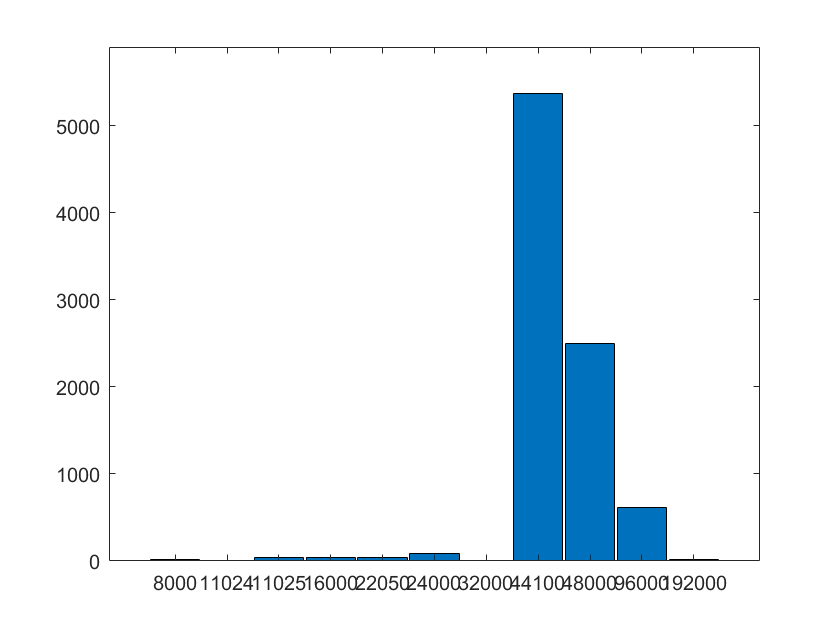

Overall2.Properties.VariableNames{1}='Bits';
Overall2.Properties.VariableNames{2}='Occurences'
figure();

hist(categorical(Bits))

ans = 44100

Overall2 = 5×2 table
     Bits     Occurences
    ______    __________

    {'0' }          9   
    {'8' }         43   
    {'16'}       5758   
    {'24'}       2753   
    {'32'}        169   


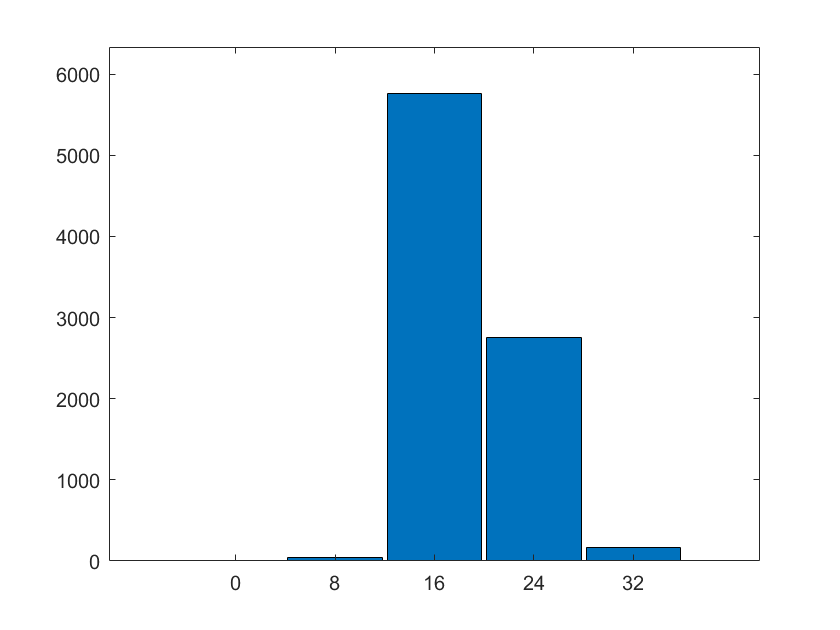

ans = 16

mode(Bits)

Observations:

- The mode of bits is 16, however, there are 9 audio videos encoded by some compression method, you may need to decode it if you want to get the bits info, however, since there are minority, I didn't take action to process them.